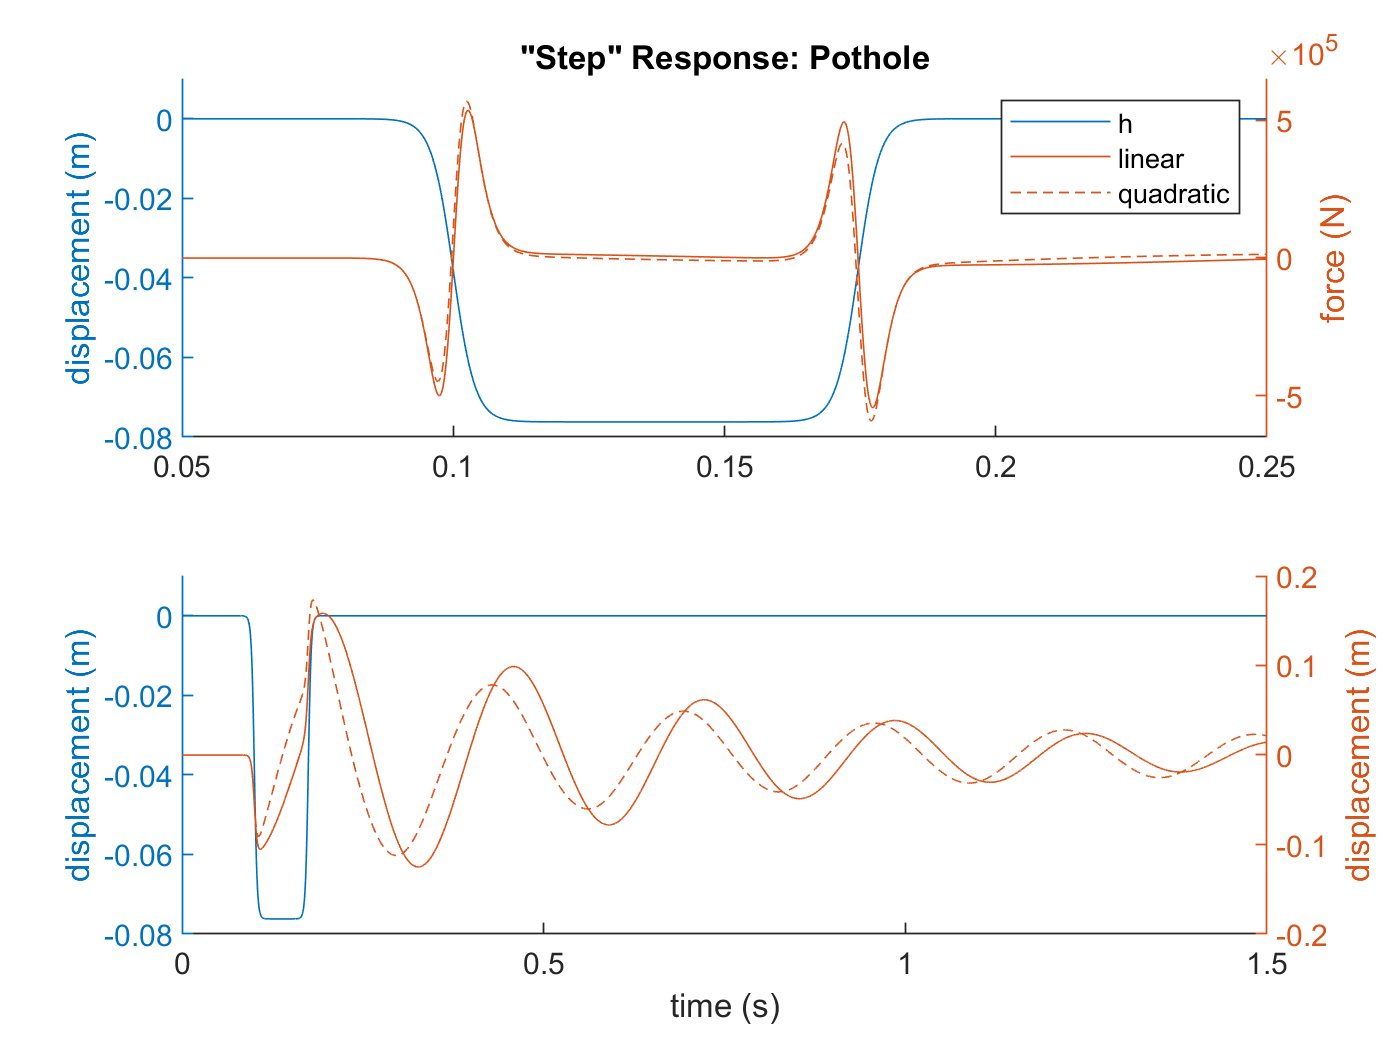

%simulation analysis
close all

time=out.tout;
h=out.h;
z_lin=out.z_linear;
z_quad=out.z_quad;
f_lin=out.f_linear;
f_quad=out.f_quad;

subplot(2,1,1);
hold on
yyaxis left
ylabel('displacement (m)')
plot(time(501:2500),h(501:2500))
ylim([-0.08,0.01])
yyaxis right
ylabel('force (N)')
plot(time(501:2500),f_lin(501:2500))
plot(time(501:2500),f_quad(501:2500))
ylim(10^5*[-6.5,6.5])
hold off
title('"Step" Response: Pothole')
legend('h','linear','quadratic')

subplot(2,1,2);
hold on
yyaxis left
ylabel('displacement (m)')
plot(time,h)
ylim([-0.08,0.01])
yyaxis right
ylabel('displacement (m)')
plot(time,z_lin)
plot(time,z_quad)
hold off
xlabel('time (s)')